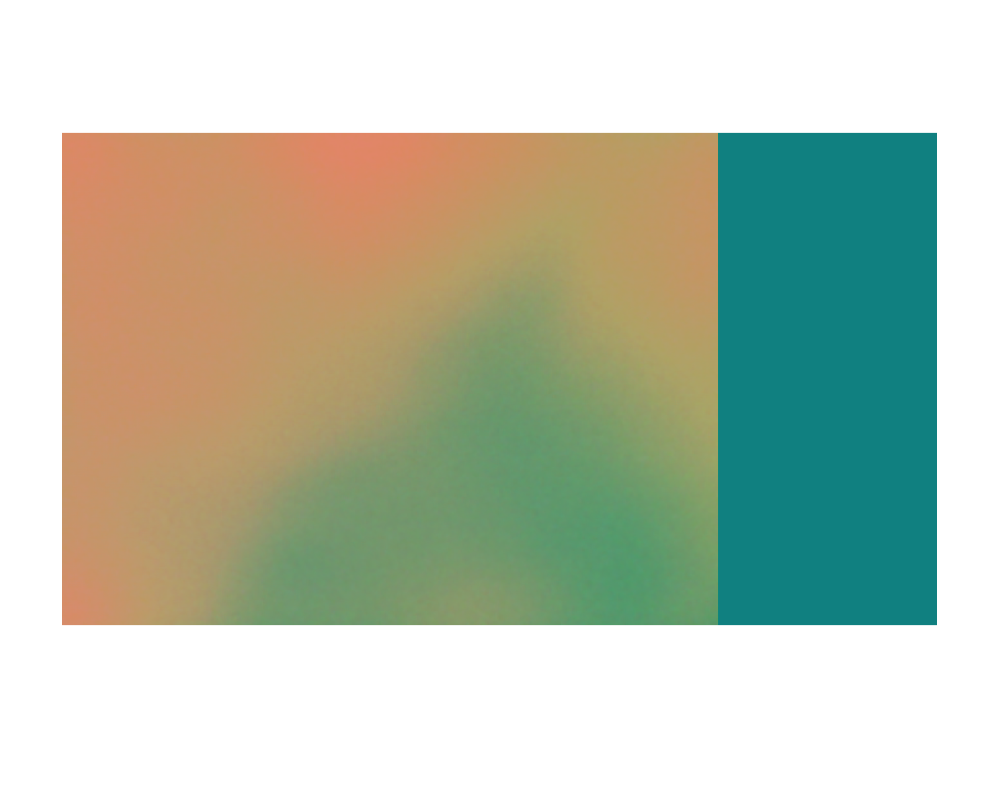

%% Adquisicion de la imagen desde webcam pasando por OBS

cam = videoinput('winvideo',2);
im = getsnapshot(cam);
figure; imshow(im);

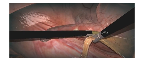

%% Reconocimiento para la imagen capturada de internet

im = imread("lap.png");
figure; imshow(im)

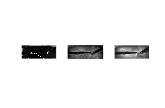

% ---- procesamiento de la imagen ---- %
imhsv = rgb2hsv(im);                            % Conversion a hsv
figure; subplot(1,3,1); imshow(imhsv(:,:,1))    % Dibujo de cada canal por separado
subplot(1,3,2); imshow(imhsv(:,:,2))
subplot(1,3,3); imshow(imhsv(:,:,3))

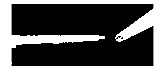

%% Extraccion de pixeles de baja saturacion de matriz V
%mascara = (imhsv(:,:,2)<0.8) .* (imhsv(:,:,3)<0.5);
mascara = not(imbinarize(imhsv(:,:,3),0.15));           % Finalmente se segmenta solo por valor (brillo) bajo --> herramienta negra
figure; imshow(mascara,[])

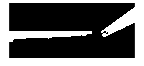

%% Mejora de la imagen segmentada con operadores morfológicos
imMej = bwmorph(mascara,'erode',6);     % Erosion  +   (Eliminar puntos del fondo)
imMej = bwmorph(imMej,'dilate',6);      % Dilatacion = Apertura ¿?
figure; imshow(imMej)

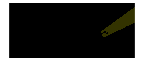

%% Etiquetado de regiones conectadas
imL = bwlabel(imMej);
figure; imshow(imL,[0 0 0; colorcube])

max(max(imL))   % Numero de regiones conectadas

ans = 2

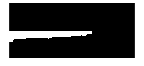

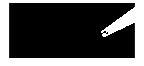

%% Visualizacion de las regiones conectadas
for i = 1:max(max(imL))
    ob = (imL == i);
    figure; imshow(ob)
end

%% Obtención de la ubicación de la punta de la herramienta para cada región conectada:

% Obtención del centroide, eje mayor del rectángulo principal, y orientación (en grados º)
props = regionprops(imMej,'Centroid','MajorAxisLength','Orientation');
k = 1;

tam = size(imMej);
tamX = tam(2);
tamY = tam(1);

% Cuanto sale la punta del canutillo
offset = 80;

clear t

% Dibujo de la im original, sobre esta se marcan puntos de interes
figure; imshow(im); hold on;

for i = 1:length(props)

    d = props(i).MajorAxisLength/2 + offset;    % Longitud de medio canutillo
    c = props(i).Centroid;                      % Centroide
    theta = props(i).Orientation*pi/180;        % Orientacion en radianes

    % Dos posibilidades para la punta de la herramienta:

    %%Pos. 1
    tx1 = c(1) + d*cos(theta);
    ty1 = c(2) - d*sin(theta);
        if ((tx1 > 0) && (tx1<tamX) && (ty1 > 0) && (ty1<tamY))     % Si el punto no se sale de la imagen, se incluye
            t(1,k) = (tx1);
            t(2,k) = (ty1);
            k = k + 1;
        end

    %%Pos. 2
    tx2 = c(1) - d*cos(theta);
    ty2 = c(2) + d*sin(theta);
        if ((tx2 > 0) && (tx2<tamX) && (ty2 > 0) && (ty2<tamY))     % Si el punto no se sale de la imagen, se incluye
            t(1,k) = (tx2);
            t(2,k) = (ty2);
            k = k + 1;
        end

end

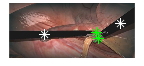

%% Dibujo de todos los puntos de interés sobre la im original
plot(t(1,:), t(2,:), 'g*')
for i = 1:length(props)
    c = props(i).Centroid;
    plot(c(1),c(2),'w*')
end

% ------------------------------------ %